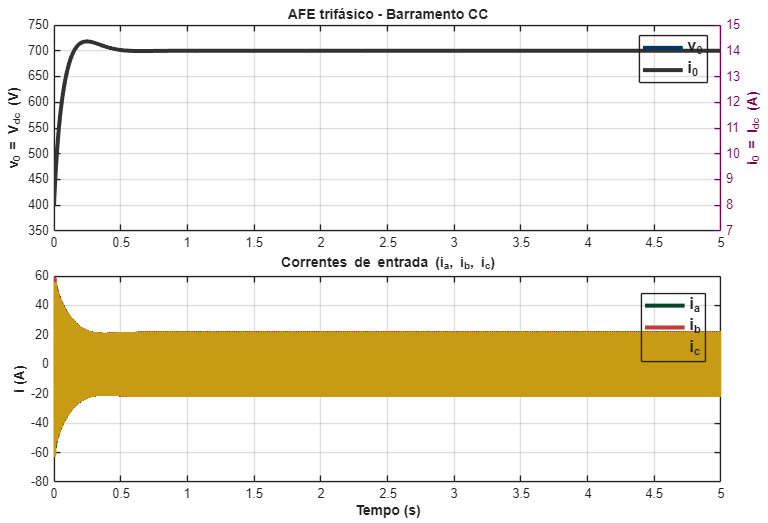

%% AFE Trifásico (Retificador Ativo) - Modelo médio com controle dq

clear; clc; close all;

f    = 60;
w    = 2*pi*f;
Vllr = 380;
Vphr = Vllr/sqrt(3);
Vphm = sqrt(2)*Vphr;

Lf   = 2.5e-3;
Rf   = 0.15;

Cdc  = 10e-3;
Rload= 50;

Vdc_ref = 700;

Kpi = 8;
Kii = 2000;

Kpv = 0.2;
Kiv = 2;

iq_ref = 0;

Imax = 100;

Ts   = 5e-6;
Tsim = 5;
t    = 0:Ts:Tsim;
N    = numel(t);

iabc  = zeros(3,N);
Vdc   = zeros(1,N);
Vdc(1)= 400;

xi_d = 0; xi_q = 0;
xv   = 0;

vsabc     = zeros(3,N);
idq_log   = zeros(2,N);
vdqcmd    = zeros(2,N);
idref_log = zeros(1,N);

Pac   = zeros(1,N);
Pload = zeros(1,N);

clarke = @(abc) (2/3)*[ 1      -1/2     -1/2;
                       0  sqrt(3)/2 -sqrt(3)/2 ]*abc;

invclarke = @(ab) [ 1,            0;
                   -1/2,  sqrt(3)/2;
                   -1/2, -sqrt(3)/2 ]*ab;

park = @(ab,th) [ cos(th)  sin(th);
                 -sin(th)  cos(th) ]*ab;

invpark = @(dq,th) [ cos(th) -sin(th);
                     sin(th)  cos(th) ]*dq;

for k = 1:N-1

    th = w*t(k);

    vsa = Vphm*cos(th);
    vsb = Vphm*cos(th - 2*pi/3);
    vsc = Vphm*cos(th + 2*pi/3);
    vs  = [vsa; vsb; vsc];
    vsabc(:,k) = vs;

    i0 = Vdc(k)/Rload;

    ev = Vdc_ref - Vdc(k);
    xv = xv + Ts*ev;
    id_ref = Kpv*ev + Kiv*xv;

    id_ref = max(min(id_ref, Imax), -Imax);
    idref_log(k) = id_ref;

    i_ab = clarke(iabc(:,k));
    i_dq = park(i_ab, th);
    idq_log(:,k) = i_dq;

    ed = id_ref - i_dq(1);
    eq = iq_ref - i_dq(2);

    xi_d = xi_d + Ts*ed;
    xi_q = xi_q + Ts*eq;

    v_ab = clarke(vs);
    v_dq = park(v_ab, th);
    v_sd = v_dq(1);
    v_sq = v_dq(2);

    u_d = Kpi*ed + Kii*xi_d;
    u_q = Kpi*eq + Kii*xi_q;

    v_cd = v_sd - Rf*i_dq(1) + w*Lf*i_dq(2) - u_d;
    v_cq = v_sq - Rf*i_dq(2) - w*Lf*i_dq(1) - u_q;

    vdqcmd(:,k) = [v_cd; v_cq];

    v_cab  = invpark([v_cd; v_cq], th);
    v_cabc = invclarke(v_cab);

    di = (vs - v_cabc - Rf*iabc(:,k))/Lf;
    iabc(:,k+1) = iabc(:,k) + Ts*di;

    Pac(k) = vs.' * iabc(:,k);
    Pload(k) = (Vdc(k)^2)/Rload;

    Vdc_safe = max(Vdc(k), 50);
    dVdc = (Pac(k) - Pload(k)) / (Cdc * Vdc_safe);

    Vdc(k+1) = Vdc(k) + Ts*dVdc;

end

vsabc(:,N)     = vsabc(:,N-1);
idq_log(:,N)   = idq_log(:,N-1);
vdqcmd(:,N)    = vdqcmd(:,N-1);
idref_log(N)   = idref_log(N-1);
Pac(N)         = Pac(N-1);
Pload(N)       = Pload(N-1);

v0 = Vdc;
i0 = Vdc./Rload;
ia = iabc(1,:); ib = iabc(2,:); ic = iabc(3,:);

statale.maincolor = [0   51  102]/255;
statale.lilla     = [120 0   80 ]/255;
statale.darkgreen = [0   70  40 ]/255;
statale.red       = [190 60  55 ]/255;
statale.yellow    = [200 155 20 ]/255;
statale.grey      = [50  50  50 ]/255;

plotColors = [
    statale.maincolor
    statale.lilla
    statale.darkgreen
    statale.red
    statale.yellow
    statale.grey
];
set(groot,'defaultAxesColorOrder',plotColors);

LW3 = 3.0;
LW2 = 2.0;
FSleg = 12;

figure('Color','w','Position',[80 80 1100 750]);
tiledlayout(2,1,"Padding","compact","TileSpacing","compact");

nexttile;
plot(t, v0, 'LineWidth', LW3, 'Color', plotColors(1,:)); grid on;
ylabel('v_0 = V_{dc} (V)','FontWeight','bold');
title('AFE trifásico - Barramento CC');

yyaxis right;
plot(t, i0, 'LineWidth', LW3, 'Color', plotColors(6,:)); grid on;
ylabel('i_0 = I_{dc} (A)','FontWeight','bold');

lgd = legend('v_0','i_0','Location','best');
lgd.FontSize = FSleg; lgd.FontWeight = 'bold'; lgd.Color = 'none';

ax = gca;
ax.XLabel.FontWeight = 'bold';
ax.YLabel.FontWeight = 'bold';

nexttile;
plot(t, ia, 'LineWidth', LW3, 'Color', plotColors(3,:)); hold on;
plot(t, ib, 'LineWidth', LW3, 'Color', plotColors(4,:));
plot(t, ic, 'LineWidth', LW3, 'Color', plotColors(5,:));
grid on;
xlabel('Tempo (s)','FontWeight','bold');
ylabel('i (A)','FontWeight','bold');
title('Correntes de entrada (i_a, i_b, i_c)');

lgd = legend('i_a','i_b','i_c','Location','best');
lgd.FontSize = FSleg; lgd.FontWeight = 'bold'; lgd.Color = 'none';

ax = gca;
ax.XLabel.FontWeight = 'bold';
ax.YLabel.FontWeight = 'bold';

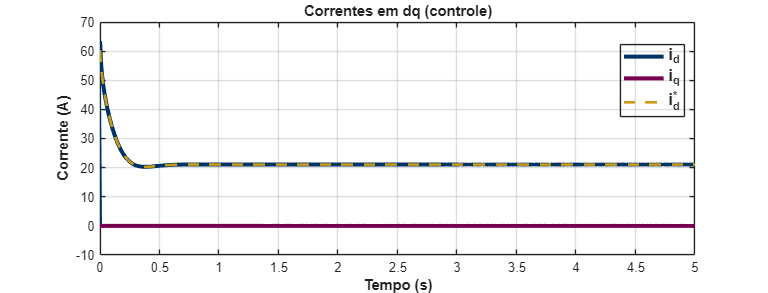


figure('Color','w','Position',[150 150 1100 420]);
plot(t, idq_log(1,:), 'LineWidth', LW3, 'Color', plotColors(1,:)); hold on;
plot(t, idq_log(2,:), 'LineWidth', LW3, 'Color', plotColors(2,:));
plot(t, idref_log, '--', 'LineWidth', LW2, 'Color', plotColors(5,:));
grid on;
xlabel('Tempo (s)','FontWeight','bold');
ylabel('Corrente (A)','FontWeight','bold');
title('Correntes em dq (controle)');

lgd = legend('i_d','i_q','i_d^*','Location','best');
lgd.FontSize = FSleg; lgd.FontWeight = 'bold'; lgd.Color = 'none';

ax = gca;
ax.XLabel.FontWeight = 'bold';
ax.YLabel.FontWeight = 'bold';